# $\frac{F}{D}$ Test bench

## Versions

13.07.2023 - Dominique Humbert - Original version

## Hypothesis

HES matrix is compuded using thin lens and paraxial approximations. and is based on "Introduction à l'optique pour les ingénieurs", 2020, Laurent Jolissaint, HEIG-VD.

## Layout

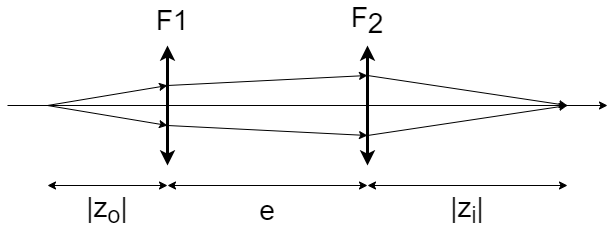

**Aperture control needs to be done**

## Input parameters

F_original = 25100; % [mm]
D_original = 450;   % [mm]

f1 = 40;            % [mm]
f2 = 200;           % [mm]
A = 10;             % [mm] Aperture diameter

zo_min = 20;        % [mm] absolute value
zo_max = 50;        % [mm] absolute value
zi_min = 10;        % [mm]
zi_max = 500;       % [mm]
z_increment = 1;    % [mm]

e_min = 10;         % [mm]
e_max = 500;        % [mm]
e_increment = 1;    % [mm]

df1 = 1;            % [mm]
df2 = 1;            % [mm]
de = e_increment;   % [mm]
dA = 0.2;           % [mm]

effective_zo = -32;  % [mm]
effective_zi = 412.526;% [mm] 

SavePath = '\\wsl.localhost\Ubuntu-20.04\home\dominique\Rapport\template-tb-main\assets\figures\zi_zo_test_bench.png';
SAVEFIG = false;     % Allows for plot saving. true = save

## Algorithm

V1 = 1/f1;
V2 = 1/f2;

e = e_min;
fd = 0;
FD = F_original/D_original;
while fd < FD
    if e > e_max
        fprintf('e is out of bounds')
        break
    else
        e = e+e_increment;
        V = (V2+V1 -V1*V2*e);
        F = 1/V;
        fd = F/A;
    end
end

HES1 = [1-V1*e e;-V 1-V2*e];

EHo = (-1/V)*(HES1(2,2) -1);
SHi = (1/V)*(HES1(1,1) -1);

dF = abs((f1*(f1+f2-e)-f1*f2)/(f1+f2-e)^2)*df1 + abs((f2*(f1+f2-e)-f1*f2)/(f1+f2-e)^2)*df2 + abs(((f1*f2)/(f1+f2-e)^2))*de;
dF = ceil(dF);
dfd = ((dF/abs(F) + dA/A)*fd);


zo = -zo_max:z_increment:-zo_min;
po = zo - EHo;
pi = po./(V*po + 1);
zi = pi + SHi;

## Output

temptext = sprintf(['---------- Preliminary results --------\n' ...
    'Input parameters:\n' ...
    '\tOriginal F: %d mm\n' ...
    '\tOriginal D: %d mm\n' ...
    '\t\tf1: %d mm\n' ...
    '\t\tf2: %d mm\n' ...
    '\t\tD: %.2f mm\n' ...
    '\t%.2f < e < %2.f mm\n' ...
    '\t%.2f < zo < %2.f mm\n' ...
    '\t%.2f < zi < %2.f mm\n' ...
    '\te increment: %.2f mm\n' ...
    '\tz increment: %.2f mm\n' ...
    'Results:\n' ...
    '\toriginal F/D: %.2f\n' ...
    '\tcomputed F/D: %.1f +/- %.1f\n' ...
    '\t\te: %.f +/- %.f mm\n' ...
    '\tequivalent focal: %.f +/- %.f mm\n' ...
    '---------------------------------------\n'],[F_original,D_original,f1,f2, ...
    A,e_min,e_max,-zo_max,-zo_min,zi_max,zi_min ...
    e_increment, z_increment,FD,fd,dfd,e,de,1/V,dF]);

fprintf(temptext)

---------- Preliminary results --------
Input parameters:
	Original F: 25100 mm
	Original D: 450 mm
		f1: 40 mm
		f2: 200 mm
		D: 10.00 mm
	10.00 < e < 500 mm
	-50.00 < zo < -20 mm
	500.00 < zi < 10 mm
	e increment: 1.00 mm
	z increment: 1.00 mm
Results:
	original F/D: 55.78
	computed F/D: 57.1 +/- 11.7
		e: 226 +/- 1 mm
	equivalent focal: 571 +/- 106 mm
---------------------------------------


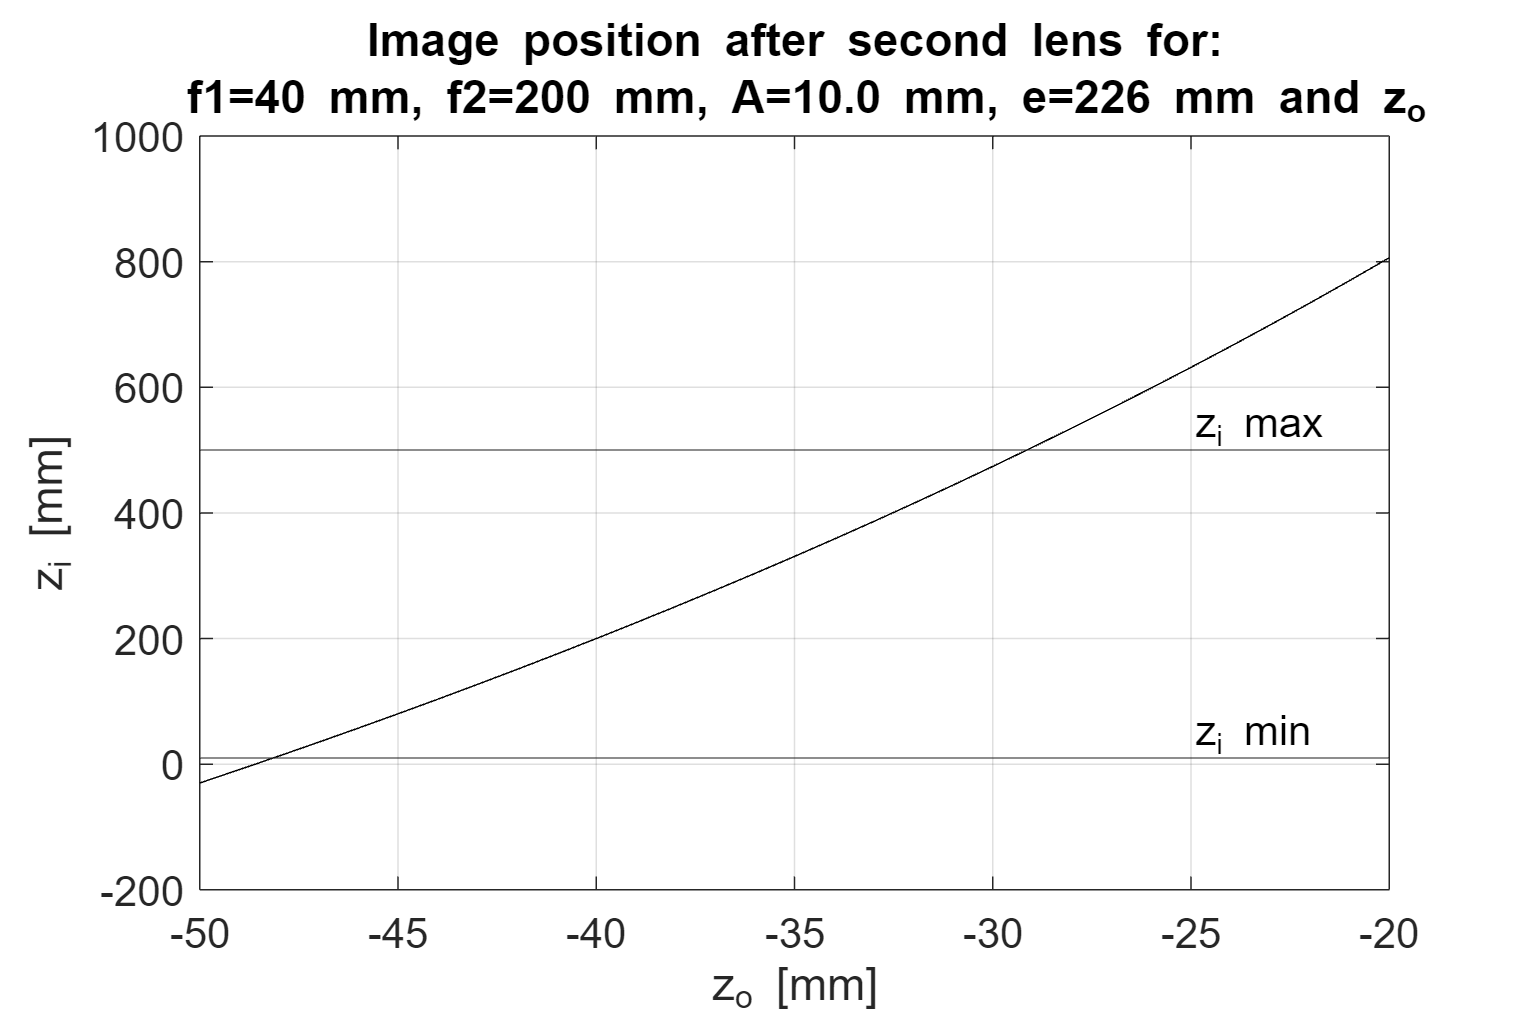


figure('Position', [10 10 900 600])
plot(zo,zi,'k')
yline(zi_min)
text(-25,535,'z_i max',"FontSize",14)
yline(zi_max)
text(-25,45,'z_i min',"FontSize",14)
grid on

temptext = sprintf('Image position after second lens for:\n f1=%d mm, f2=%d mm, A=%.1f mm, e=%d mm and z_o',f1, f2,A, e);
title(temptext)
ylabel('z_i [mm]')
xlabel('z_o [mm]')
set(gca,'FontSize',14)


if(SAVEFIG)
    saveas(gcf,SavePath)
end

## 
$$z_i(z_o)$$


zo = -32;
po = zo - EHo;
pi = po./(V*po + 1);
zi = pi + SHi;


## Effective focal length dan F/D

po = -effective_zo + EHo;
pi = -effective_zi + SHi;


dpo = (1/abs(effective_zo))*abs(po);
dpi = (1/abs(effective_zi))*abs(pi);

V = 1/po - 1/pi;
F = 1/V;
dF = abs((po*(pi-po)/(pi-po)^2))*dpo + abs((pi*(pi-po)/(pi-po)^2))*dpi;



temptext = sprintf(['------ Results with measurments -------\n' ...
    'Input parameters:\n' ...
    '\tOriginal F: %d mm\n' ...
    '\tOriginal D: %d mm\n' ...
    '\t\tf1: %d mm\n' ...
    '\t\tf2: %d mm\n' ...
    '\t\tD: %.2f mm\n' ...
    '\t%.2f < e < %2.f mm\n' ...
    '\t%.2f < zo < %2.f mm\n' ...
    '\t%.2f < zi < %2.f mm\n' ...
    '\te increment: %.2f mm\n' ...
    '\tz increment: %.2f mm\n' ...
    'Results:\n' ...
    '\toriginal F/D: %.2f\n' ...
    '\tcomputed F/D: %.1f +/- %.1f\n' ...
    '\t\te: %.f +/- %.f mm\n' ...
    '\tequivalent focal: %.f +/- %.f mm\n' ...
    '---------------------------------------\n'],[F_original,D_original,f1,f2, ...
    A,e_min,e_max,-zo_max,-zo_min,zi_max,zi_min ...
    e_increment, z_increment,FD,fd,dfd,e,de,1/V,dF]);

fprintf(temptext)

------ Results with measurments -------
Input parameters:
	Original F: 25100 mm
	Original D: 450 mm
		f1: 40 mm
		f2: 200 mm
		D: 10.00 mm
	10.00 < e < 500 mm
	-50.00 < zo < -20 mm
	500.00 < zi < 10 mm
	e increment: 1.00 mm
	z increment: 1.00 mm
Results:
	original F/D: 55.78
	computed F/D: 57.1 +/- 11.7
		e: 226 +/- 1 mm
	equivalent focal: 571 +/- 11 mm
---------------------------------------
